## **Image Processing**

**Dependencies:**

- **Image processing toolbox**

Image processing is the process by which some operations are performed on an image in order to get an enhanced image or to extract some useful information from it.

Image processing was responsible for mapping out the location of the boxes on the checkerboard such that when a speech input such as “C4” was issued, the manipulator would actually move to the x-y coordinates of the desired point.

- **Creating a virtual board (checkerboard image) and its complement.**

Since tracking of the game state was not the focus of this research, a virtual board as opposed to a real image of the checkerboard was opted for. A binary rectangular checkerboard that is 4 tiles high and 4 tiles wide and the side of every square is 80 pixels in length was created.

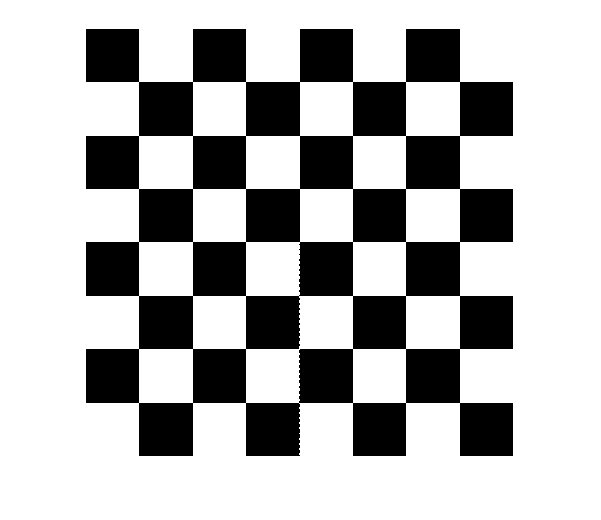

virtual_board = checkerboard(80, 4, 4) > 0.5;
imshow(virtual_board)


% pixel dimensions of the virtual board
[r c] = size(virtual_board)

r = 640

c = 640

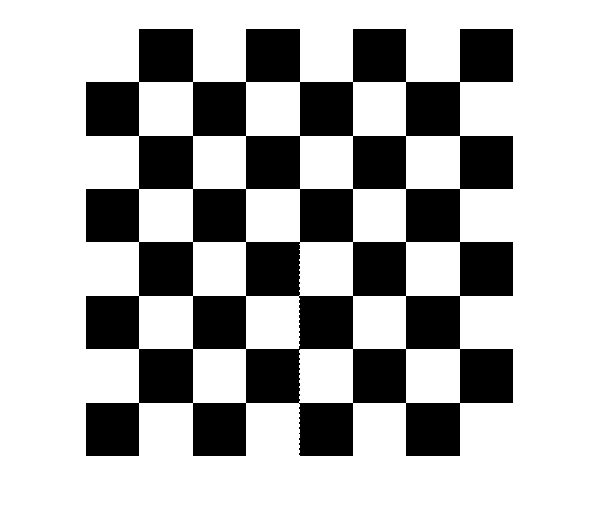


% complementing the image
virtual_board_comp = imcomplement(virtual_board);
imshow(virtual_board_comp)

**2.  Detecting the checkerboard boxes using CCL.**

To detect the individual boxes, the[ Connected Component Labelling (CCL)](https://en.m.wikipedia.org/wiki/Connected-component_labeling) technique as was used. In this approach, the black boxes with a pixel intensity value of 0 were treated as a background while the white boxes with a pixel intensity of 255 were treated as the foreground. The connected regions, in this case the white boxes, were detected using the 4-connected neighborhood approach. 4-connected pixels are neighbors to every pixel that touches one of their edges. These pixels are connected horizontally and vertically. The 4-connected CCL algorithm was successful in extracting all the white boxes and then applied to the complement image to detect the remaining boxes. Each detected box was assigned a different color.

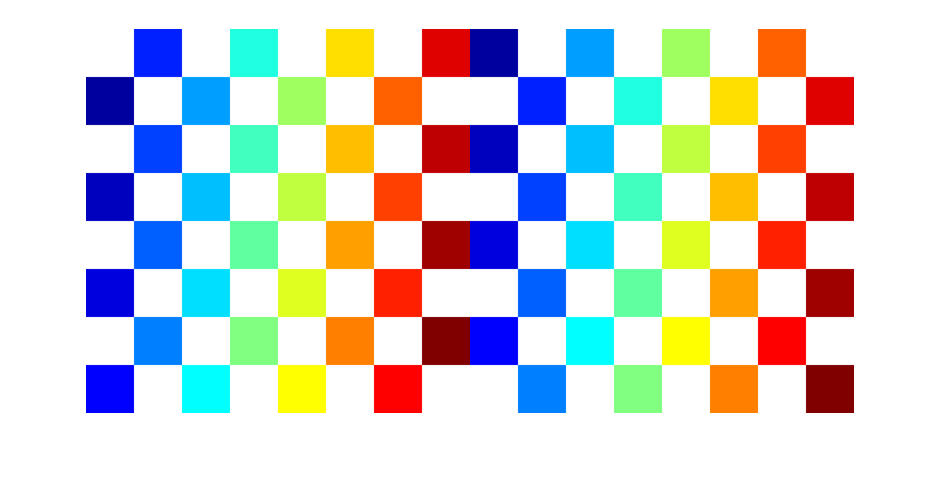

% detecting the white boxes
% finding the connected objects in a binary image
CC = bwconncomp(virtual_board, 4);
L = labelmatrix(CC);
% convert label matrix to RGB
RGB = label2rgb(L);



% detecting the black boxes
% finding the connected objects in a binary image
CC_comp = bwconncomp(virtual_board_comp, 4);
L_comp = labelmatrix(CC_comp);
% convert label matrix to RGB
RGB_comp = label2rgb(L_comp);
montage({RGB, RGB_comp})

`3. `**Extracting the centroid pixel coordinates of the detected boxes.**

Once every box was detected, the subsequent step was to extract the centroid pixel coordinates of each box. These coordinates are the markers that would identify each particular box. The centroid is the average of the x-y coordinates of the pixels in the detected object.

% extracting the centroid coordinates
centro = regionprops(L, 'Centroid');
centro_comp = regionprops(L_comp, 'Centroid');

**4. Combining the sets of centroid coordinates**

The next step is to combine the centroid coordinates of the detected boxes in the binary image and its complement.

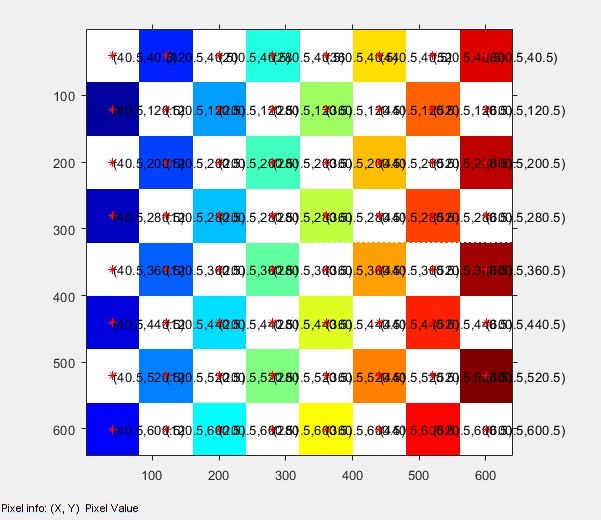

combined_cent = {};
if max(centro_comp(1).Centroid>centro(1).Centroid) == 0
for i = 1:length(centro)
   combined_cent = [combined_cent, centro_comp(i).Centroid];
   combined_cent = [combined_cent, centro(i).Centroid];
end
else
   for i = 1:length(centro)
   combined_cent = [combined_cent, centro(i).Centroid];
   combined_cent = [combined_cent, centro_comp(i).Centroid];
   end
    
end
combined_cent = combined_cent';

combined_cent_array = cell2mat(combined_cent);
combined_cent_array(:,2) = repmat(unique(combined_cent_array(:,2)), length(combined_cent_array)/length(unique(combined_cent_array(:,2))), 1);

for i = 1:length(combined_cent_array)
    checker_bd{i} = [combined_cent_array(i,1), combined_cent_array(i,2)];
end
checker_bd = checker_bd';


% plot of centroid coordinates
figure;imshow(RGB)
hold on;
for i = 1 : length(checker_bd)
plot(checker_bd{i,1}(1,1), checker_bd{i,1}(1,2), 'r*')
text(checker_bd{i,1}(1,1), checker_bd{i,1}(1,2), [ '(' num2str(checker_bd{i,1}(1,1)) ',' num2str(checker_bd{i,1}(1,2)) ')' ])
end
impixelinfo
axis on

**4. Mapping pixel values to manipulator workspace (cm) coordinates.**

The centroid coordinates are then mapped from pixel coordinates into real world x-y coordinates that the manipulator needs to arrive at in order to pick or place a chess piece. The length of the virtual board is mapped from **0 **to **640 **px to manipulator workspace **-9 **to -**9 (cm). **The width is consequently mapped from **0 **to **192 **px to **11 **to **17 **cm.

% Mapping pixel values to board coordinates
for i = 1:length(combined_cent_array)
    real_board_coord{i} =  [mapfun(combined_cent_array(i,1), 0, r, 9, -9),mapfun(combined_cent_array(i,2), 0, 192, 11, 17)];
end
real_board_coord = real_board_coord';

**5. Assigning board coordinates to their respective box names**

With all the boxes detected and their centroid pixel values known, the boxes could then be named according to the Algebraic Notation. The Algebraic Notation is the standard method for recording and describing the moves in a game of chess. Each square of the chessboard is identified by a unique coordinate pair– a letter and a number from “A1” to “H8”. Based on this convention, the boxes were named sequentially as the centroid coordinate values increased from [40.5, 40.5] (A1) to [600.5 600.5] (H8) .

%  creating key value pairs for board letter and number
key = [];
for char = ('A':'H')  
    
    for num = 1:8
    
        key = [key, {append(char, num2str(num))}];
        
    end
    
end

keySet_real = key';
valueSet_real = real_board_coord;
mapping = containers.Map(keySet_real,valueSet_real);

% adding coordintes for placing pieces outside the board
mapping('OUT') = [13 11.25]; 


% A Map object is a data structure that allows
% you to retrieve values using a corresponding key.
% For instance, to find the coordinates associated with box A1
mapping("A1")

ans =     7.8609   12.2656


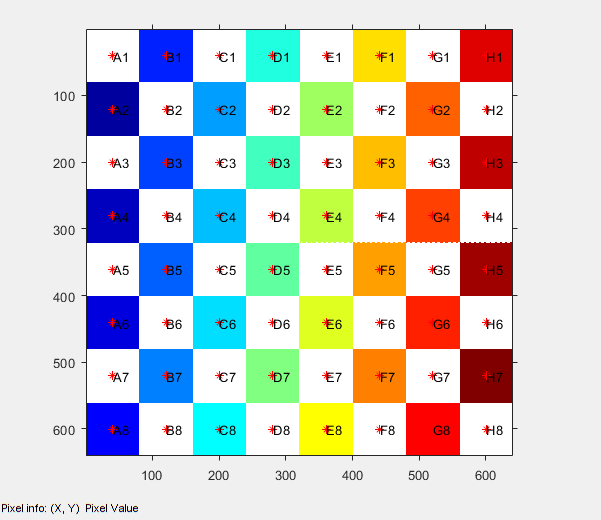


% Algebraic board
figure;imshow(RGB)
hold on;
for i = 1 : length(checker_bd)
plot(checker_bd{i,1}(1,1), checker_bd{i,1}(1,2), 'r*')
text(checker_bd{i,1}(1,1), checker_bd{i,1}(1,2), [ key{i} ])
end
impixelinfo
axis on

**Mapping function**

function output = mapfun(value,fromLow,fromHigh,toLow,toHigh)
narginchk(5,5)
nargoutchk(0,1)
output = (value - fromLow) .* (toHigh - toLow) ./ (fromHigh - fromLow) + toLow;
end
